# Extracción de características para la clasificación de fallas de bombas

Para entrenar un modelo de aprendizaje automático para detectar fallas en los datos operativos, necesitas extraer las mejores características para entrenar tu modelo. 

En este ejemplo, aprenderás a explorar, extraer y clasificar de forma interactiva funciones de dominio de tiempo y frecuencia utilizando la aplicación ***Diagnostic Feature Designer***. Luego, generarás una función de MATLAB, con la cual podrás regenerar estas características para datos nuevos y usarlas para entrenar un modelo de aprendizaje automático para identificar fallas en datos de bombas nuevas. 

## Configuración

### 1. Cargar conjunto de datos guardados

Usando este [ejemplo](https://www.mathworks.com/help/predmaint/ug/multi-class-fault-detection-using-simulated-data.html) ( `nPerGroup=30)`, generamos datos sintéticos de flujo y presión para una bomba triplex en estados normales o defectuosos. Hay 3 tipos de fallas posibles: fugas del sello, entrada bloqueada y rodamiento desgastado. La combinación de cero, una o múltiples fallas juntas da 8 posibles combinaciones de códigos de falla,** desde 000 (sin falla), 001,... a 111 (cuando todas las fallas están presentes). **

El archivo MAT `pumpDataComplete` contiene datos preprocesados, remuestreados uniformemente con los transitorios iniciales eliminados. Carga este archivo para comenzar 

clc
load pumpDataComplete.mat

### 2. Partición de datos para entrenamiento y pruebas

Reservaremos el 10% de los datos para probar el modelo predictivo, usando la función [`cvpartition`](https://la.mathworks.com/help/stats/cvpartition.html). Esto ayuda a evitar el [sobreajuste](ttps://la.mathworks.com/discovery/overfitting.html) al probar nuestro modelo entrenado con datos nuevos.

rng("default") % Para reproducibilidad
holdOutTestData = 0.1;

c = cvpartition(pumpDataInMemory.faultCode,'HoldOut',holdOutTestData);
trainData = pumpDataInMemory(training(c),:);
testData = pumpDataInMemory(test(c),:);

## Extraer características de forma interactiva usando Diagnostic Feature Designer* A*pp 

 *** Nota: Una vez que abras Diagnostic Feature Designer en MATLAB Online, puede resultar engorroso hacer clic de ida y vuelta entre la aplicación y este script. Considera usar la ***[***versión HTML***](matlab: web("HelperFiles/Work_FeatureExtraction_es.html","-browser"))*** de este script en otra ventana del navegador para seguir los pasos. ***

La aplicación [*Diagnostic Feature Designer*](https://la.mathworks.com/help/predmaint/ref/diagnosticfeaturedesigner-app.html) te permite extraer, visualizar y clasificar de forma interactiva una variedad de características a partir de datos medidos o simulados. 

### 3. Abre el *Diagnostic Feature Designer*

Comienza abriendo la aplicación *Diagnostic Feature Designer* desde la pestaña ** APPS ** en la barra de herramientas, o ejecutando el comando `diagnosticFeatureDesigner` en el script. 

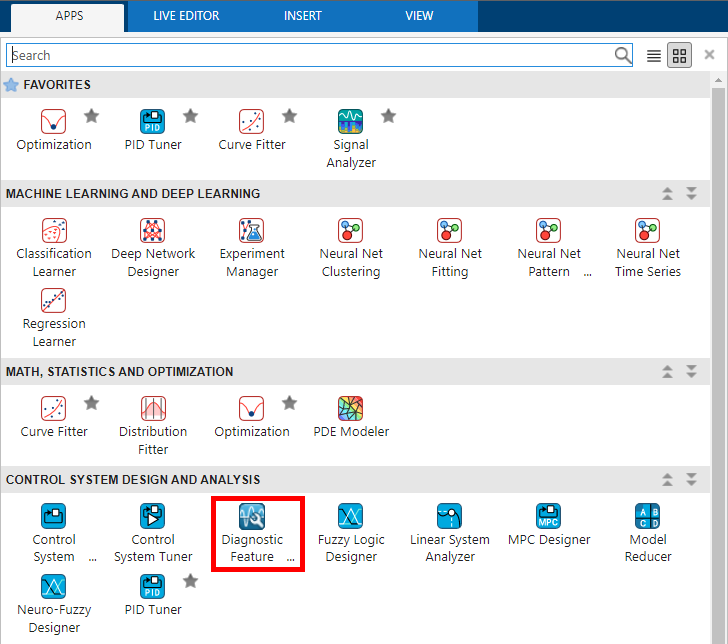

Puedes copiar y pegar el código mostrado abajo si prefieres abrir el app de esa manera

%Puedes copiar el código aquí

### 4. Cargar datos

Una vez abierta la app, inicia una *New Session* y selecciona los datos de entrenamiento del espacio de trabajo (`trainData`): 

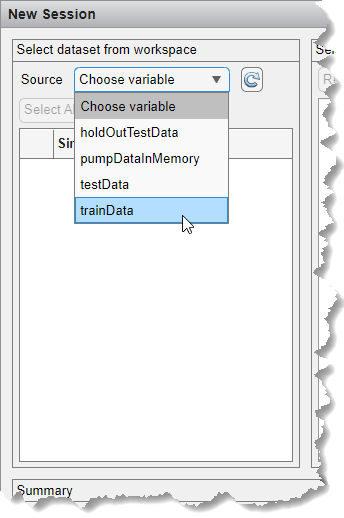

Los datos se cargan como múltiples conjuntos de datos que estaban en una sola variable.

Luego podrás revisar las distintas señales que estás importando y asignarle un nombre al conjunto. Asegúrate de que la variable `faultCode` sea una Variable de condición (**Condition Variable**). Las variables de condición indican la *condición* de la máquina y la aplicación las utiliza para agrupar y clasificar. Haz clic en **Import** cuando hayas terminado. 

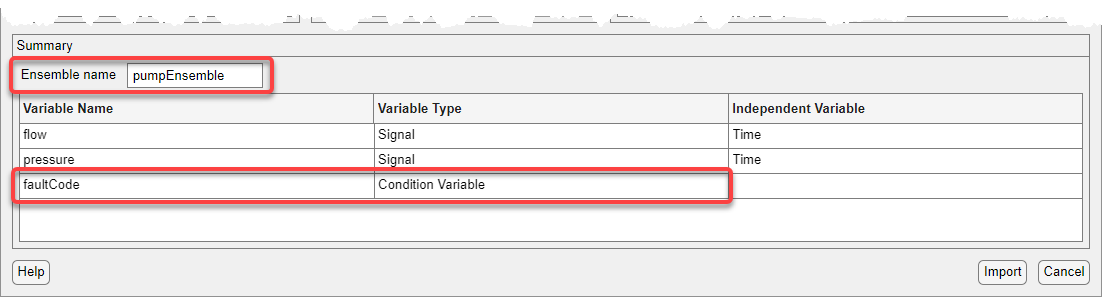

### 5. Grafica los datos

Una vez que hayas importado el conjunto de datos correctamente, puedes utilizar una gráfica de seguimiento de señales para visualizar las señales de flujo y presión. Selecciona los datos que deseas visualizar (por ejemplo, `flow`) y haz clic en ***Signal Trace***. 

 **Consejo**: Puedes realizar una selección múltiple de flujo y presión manteniendo presionada la tecla CTRL. 

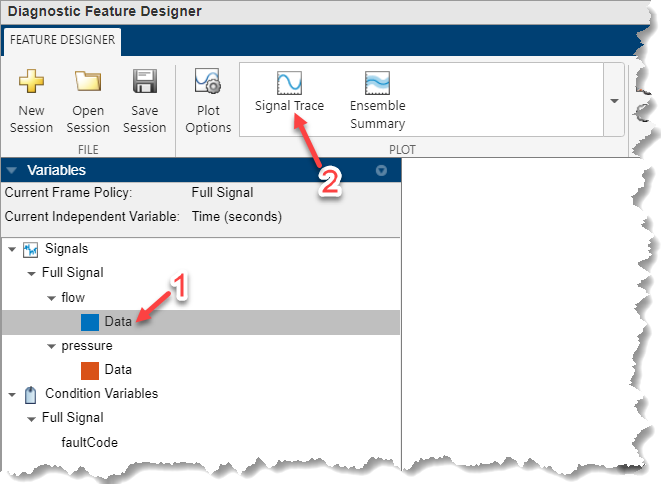

Haz esto tanto para los datos `flow` como para los datos `pressure`. Es posible que desees organizar las pestañas (arrastrando y soltando) para ver las señales una al lado de la otra: 

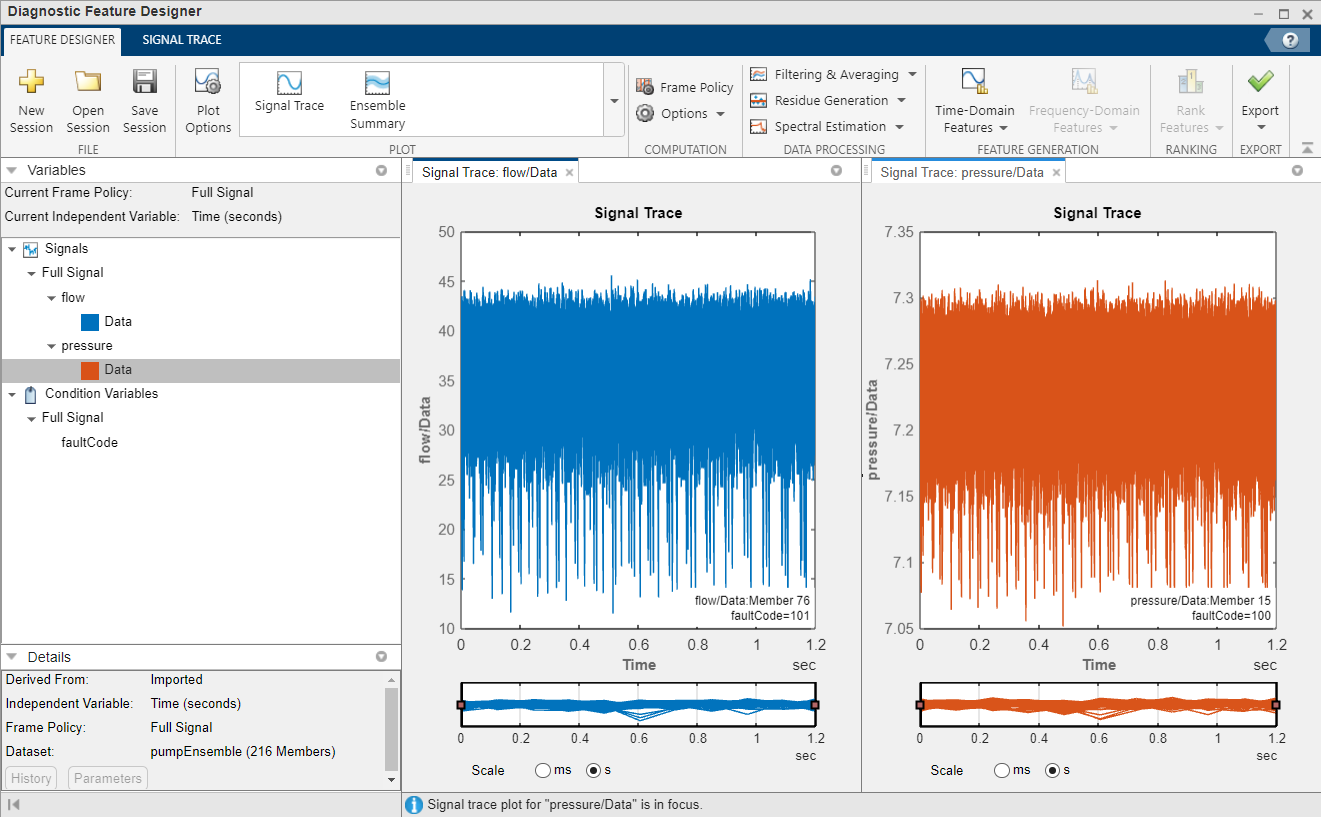

Ahora puedes agrupar las señales por cada código de falla. Para ello, ve a la pestaña **SIGNAL TRACE** y agrupa las señales por la variable de condición, usando la Opción **Group By **y seleccionando **faultCode**: 

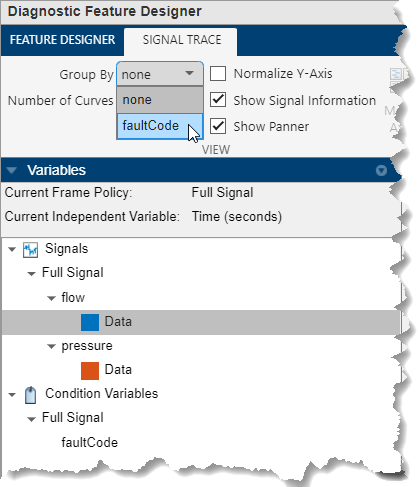

El gráfico resultante luego resaltará los datos correspondientes a diferentes fallas en diferentes colores. Puedes utilizar este gráfico para determinar rápidamente si existen diferencias claras entre los diferentes tipos de fallas. 

 Intenta hacer zoom arrastrando los bordes del panel debajo del gráfico. **¡Es difícil notar a simple vista la diferencia en cada código de falla!** Es por eso que necesitamos extraer funciones que puedan separar mejor nuestros datos entre los diferentes códigos de falla. 

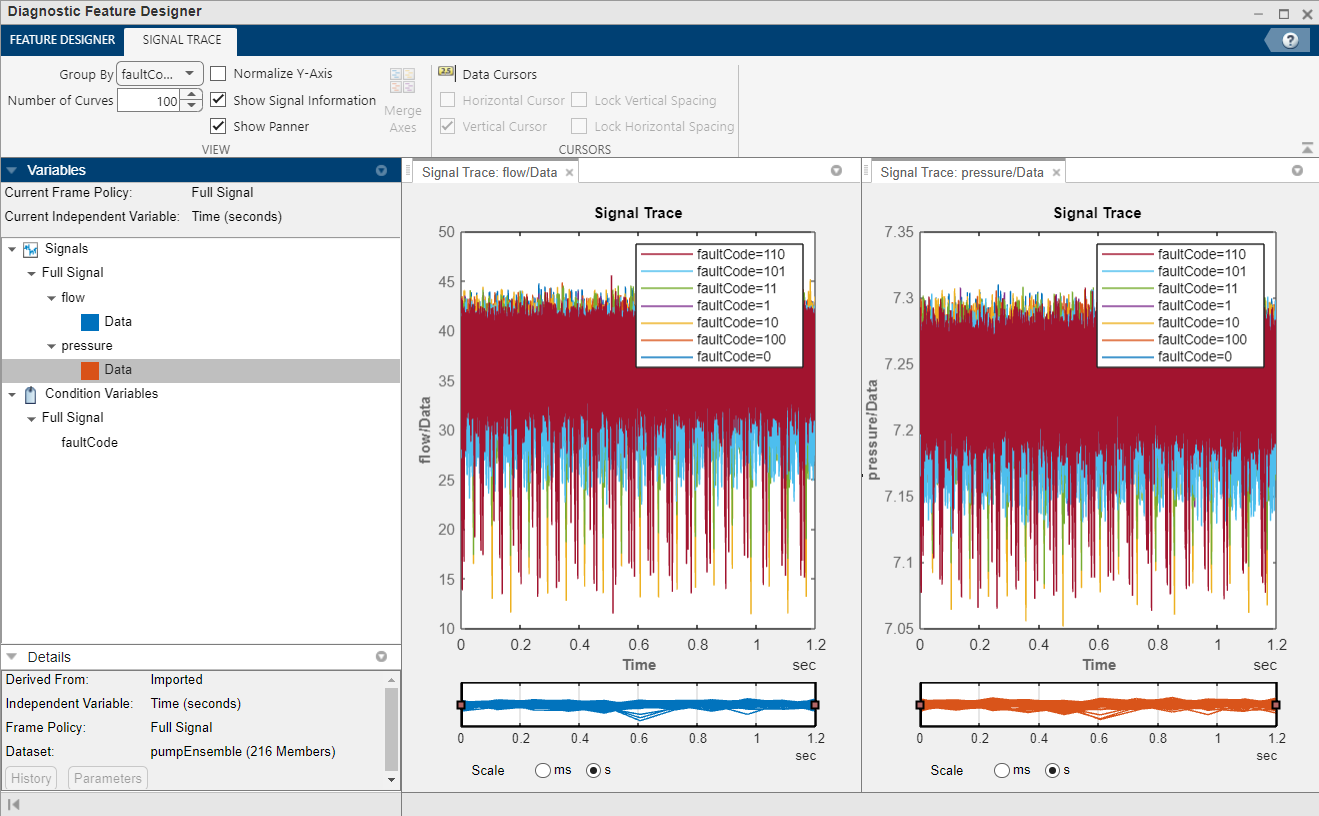

### 6. Extraer funciones en el dominio del tiempo

Hay muchos tipos de funciones que se pueden explorar en esta app. Comienza extrayendo algunas características simples en el dominio del tiempo utilizando la señal completa, como el valor medio, la desviación estándar, etc. 

 En la pestaña **FEATURE DESIGNER**, abre el cuadro de diálogo ***Time-Domain Features*** y selecciona ***Signal Features*** para los datos `flow`: 

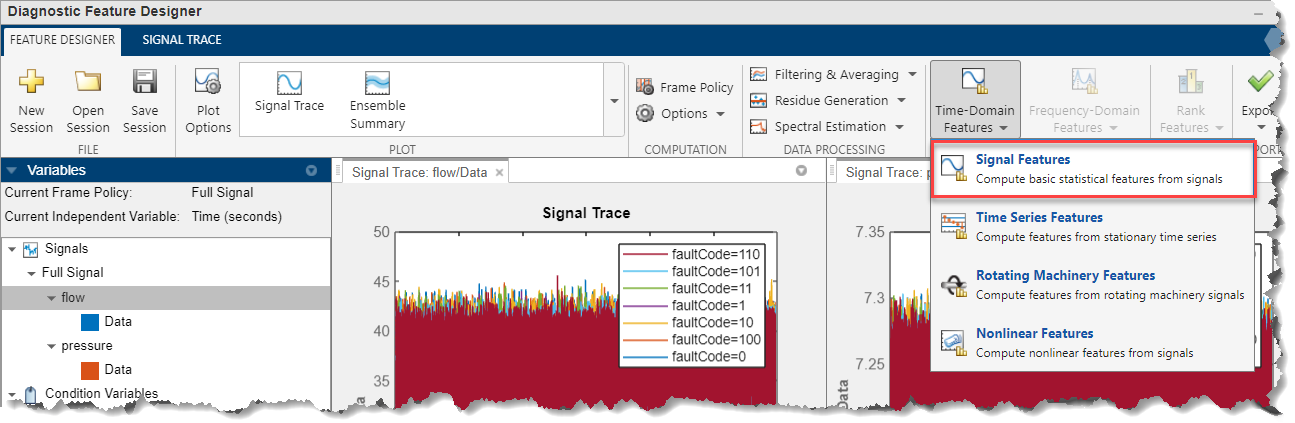

   Revisa las características que se extraerán y presiona `Apply`: 

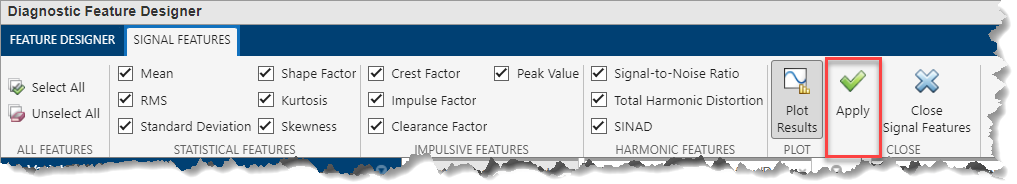

Las características estadísticas, impulsivas y armónicas se han calculado y ahora aparecerán en la Tabla de características (Feature Table) en el panel Variables: 

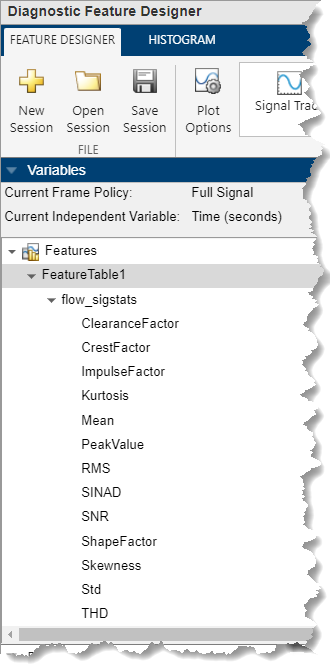

  Una vez que hayas extraído características en el dominio del tiempo de la señal `flow`, **repite el mismo proceso para extraer características en el dominio del tiempo de la señal **`pressure`**. **

  Una vez que hayas extraído las características en el dominio del tiempo de las señales `flow` y `pressure`, revisa las características calculadas en el dominio del tiempo mirando el histograma (Histogram), la vista de tabla de características (Feature Table View) o el seguimiento de características (Feature Trace) en la sección PLOT

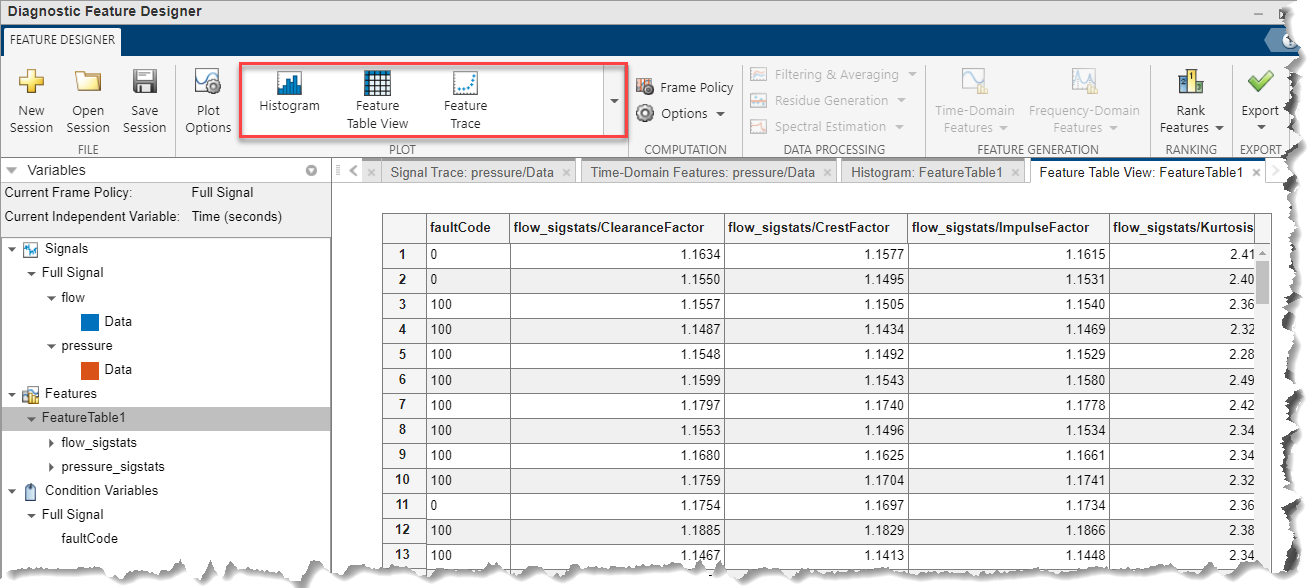

### 7. Calcular el Espectro de Potencia

Ahora has extraído algunas características en el dominio del tiempo para las señales `flow` y `pressure`. 

  Pero intenta ampliar uno de los gráficos de seguimiento de señales utilizando el control panorámico en la parte inferior; **parece haber algún comportamiento periódico**. Por lo tanto, podría resultar útil observar también las características en el dominio de la frecuencia. 

Para estimar las características en el dominio de la frecuencia, primero necesitarás extraer un **espectro de potencia **de cada señal. Existen varios métodos que puede utilizar para calcular el espectro de potencia. En este caso, calcularemos un modelo autorregresivo utilizando un orden de modelo de 20. Esto ajusta un modelo autorregresivo del orden prescrito a los datos y luego calcula el espectro de ese modelo estimado. Esto reduce cualquier sobreajuste de la señal de datos sin procesar. 

  Selecciona la señal `flow` y dentro de la sección ***Power Spectrum ***abre el menú desplegable ***Spectral Estimation*** y selecciona ***Autoregressive Model ***

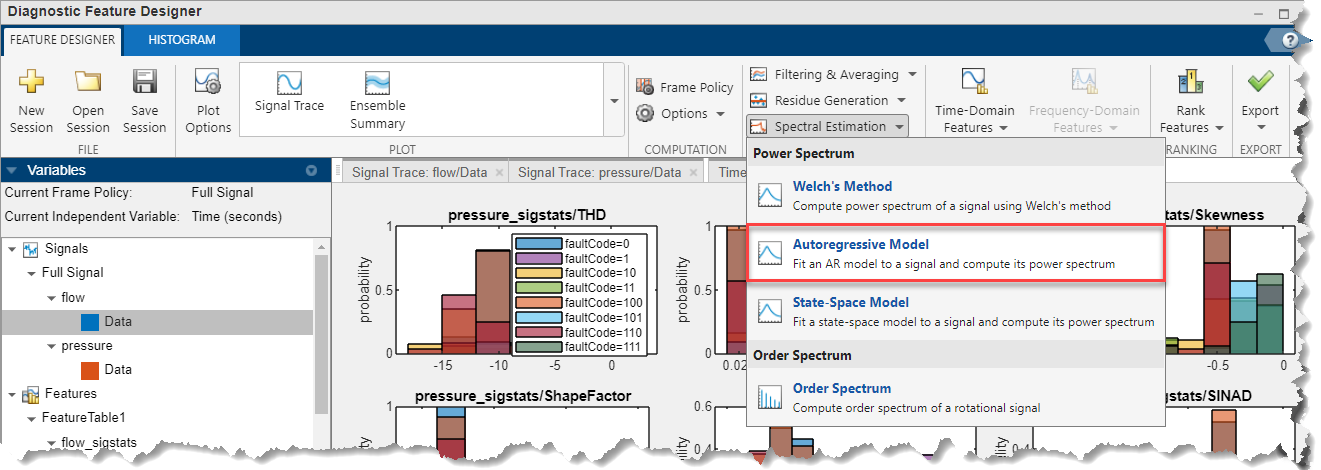

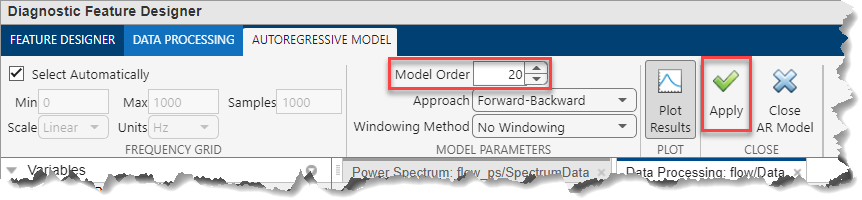

Esto calcula el espectro para cada una de las **216** señales de flujo en el conjunto de entrenamiento. 

  En la pestaña **POWER SPECTRUM**, agrupa los datos espectrales por `faultCode` y elige la opción linear para la escala X. 

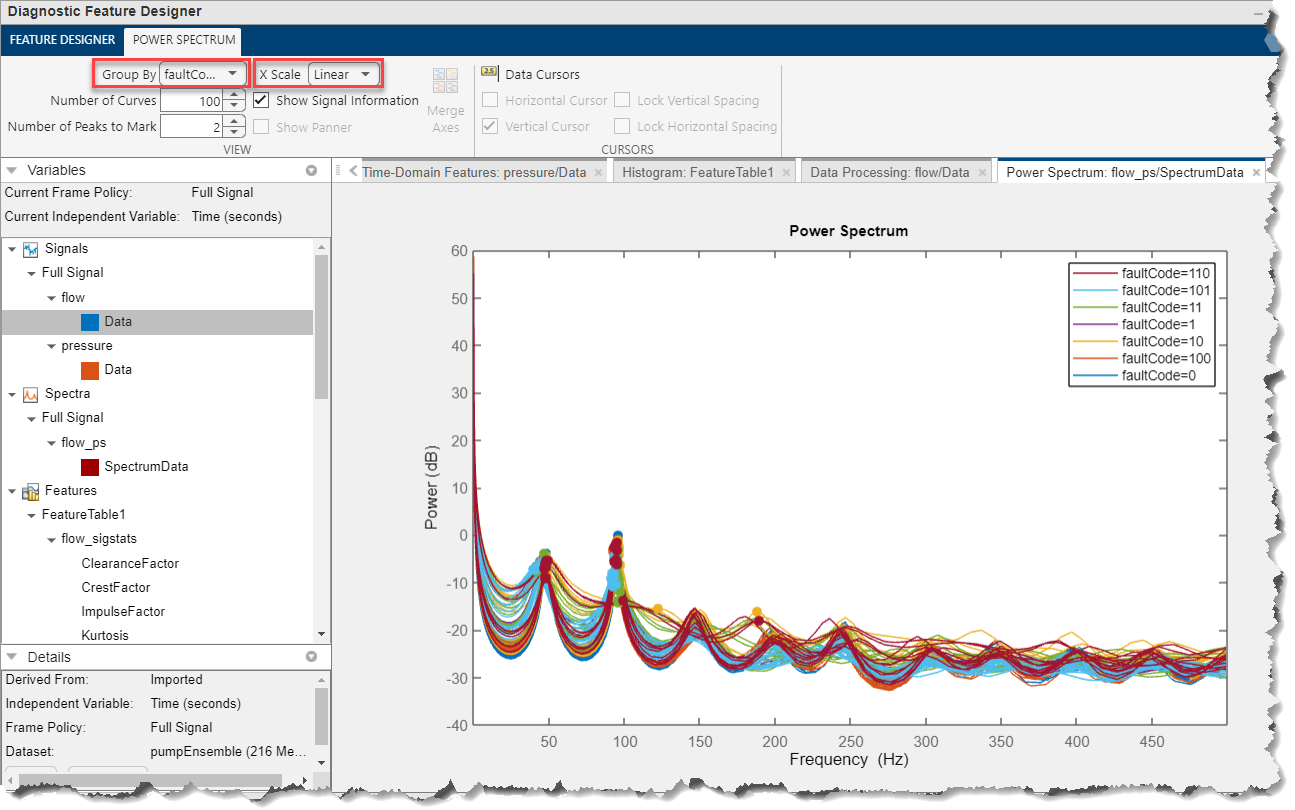

**Puedes ver que los máximos espectrales se distinguen claramente. Esto es lo que queremos ver. **

  Repite este proceso para la señal `pressure`. 

### 8. Extraer características en el dominio de frecuencia

Una vez que tengas los espectros autorregresivos para las señales de presión y flujo, puedes calcular características espectrales como máximos espectrales, coeficientes modales y potencia de banda. 

  Para ello, haz clic en la opción **Frequency-Domain Features **y luego selecciona **Spectral Features**.

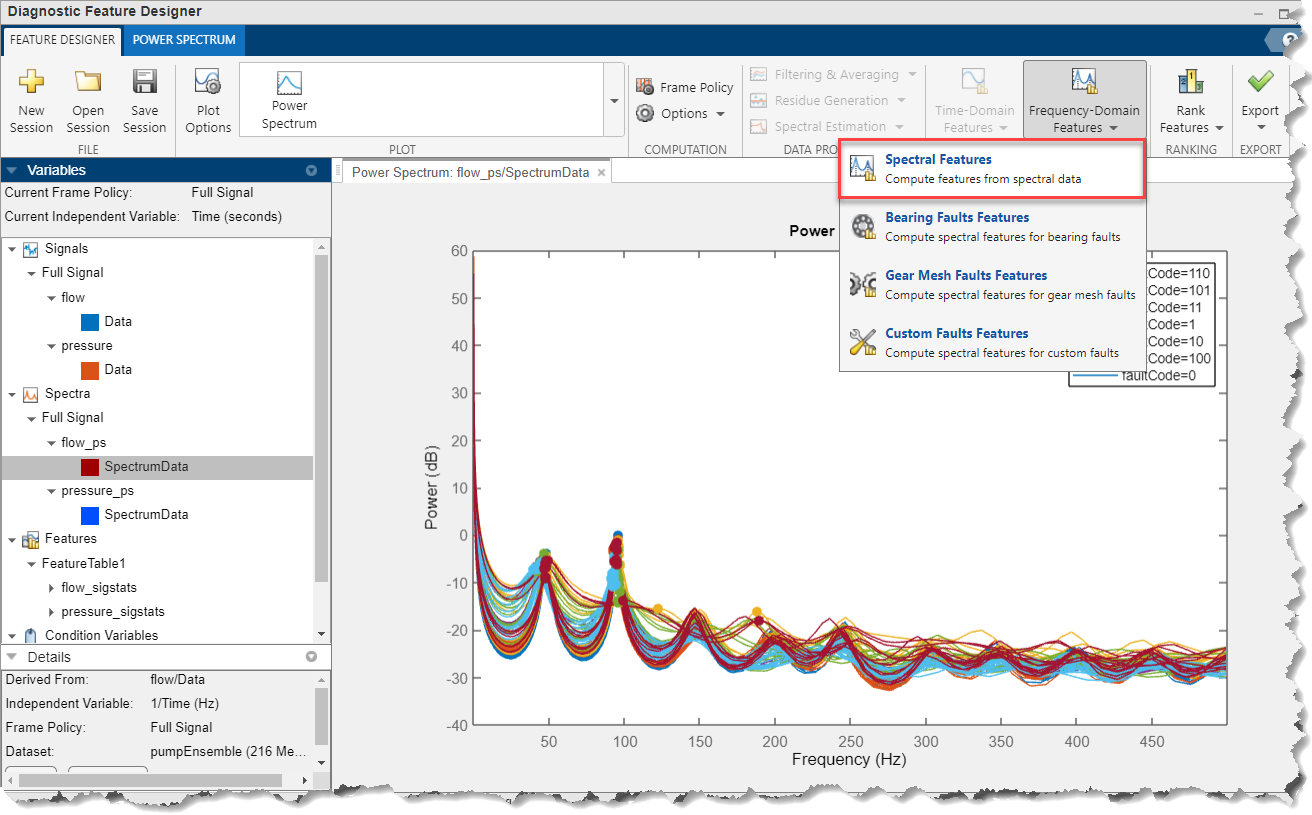

Extrae estas características en una banda más pequeña de frecuencias entre `23-250 Hz` ya que los máximos después de `250 Hz` son más pequeños. Es más difícil distinguir los máximos en frecuencias más altas. Ten en cuenta que estás extrayendo 5 máximos espectrales para cada señal. 

  Por ahora, desmarca la casilla de verificación *Plot results*. Graficarás los resultados más adelante para ver si estas características ayudan a distinguir diferentes condiciones de falla. 

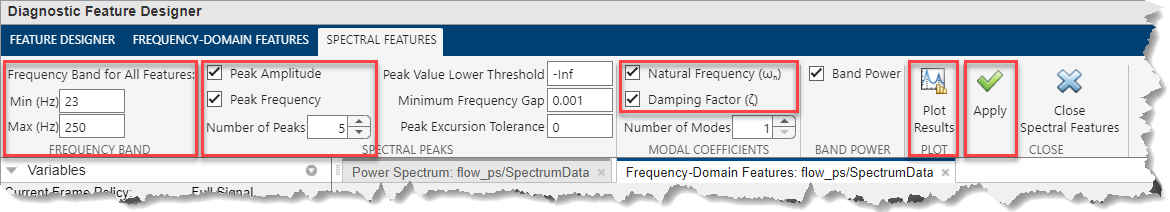

   **Repite este proceso para la señal **`pressure`**. **

### 9. Visualizar funciones

Todas las funciones que has extraído se han recopilado en una tabla que se muestra en el navegador de Feature Tables. 

  Para ver las características, selecciona la tabla `FeatureTable1` y haz clic en *Feature Table View *de la galería PLOT: 

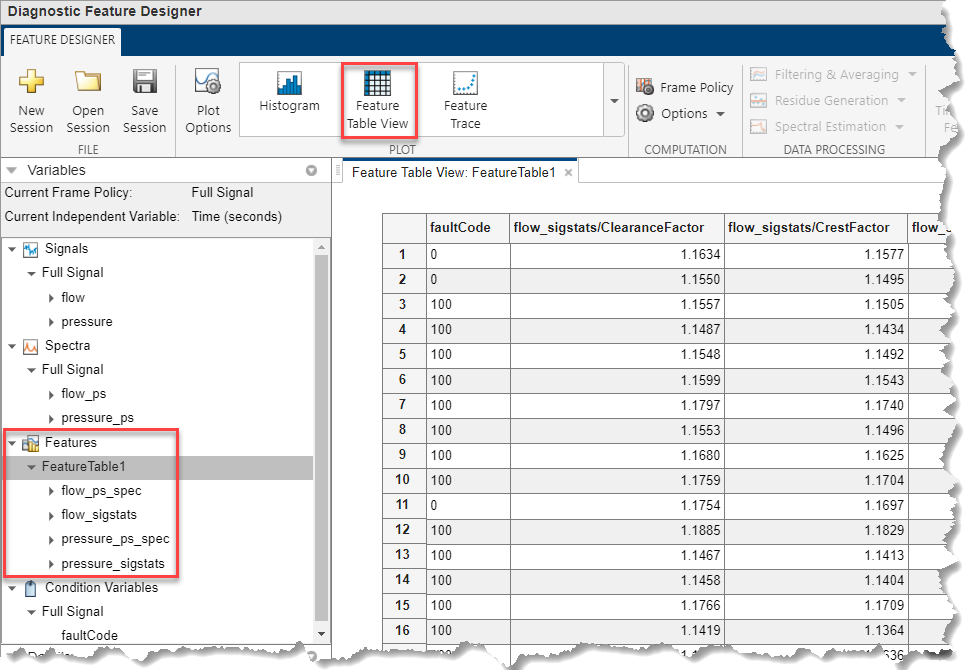

Cada fila corresponde a un conjunto de datos particular del conjunto, y los valores de las columnas para esa fila representan los diferentes valores de las características para ese conjunto de datos en particular. A medida que calculabas más funciones, se agregaban más columnas a la tabla. 

Cuando se ve como un histograma (galería PLOT > * Histograma*), puedes ver las distribuciones de los valores de las características para diferentes valores de variables de condición, es decir, tipos de fallas. 

 Los gráficos de histograma agrupados por código de falla pueden ayudar a determinar si ciertas características son fuertes diferenciadores entre tipos de fallas. Si son fuertes diferenciadores, sus distribuciones serán más distantes entre sí. Para la bomba triplex, las distribuciones de características tienden a superponerse bastante. La siguiente sección analiza el uso de la clasificación automatizada para encontrar qué funciones son más útiles para la predicción de fallas. 

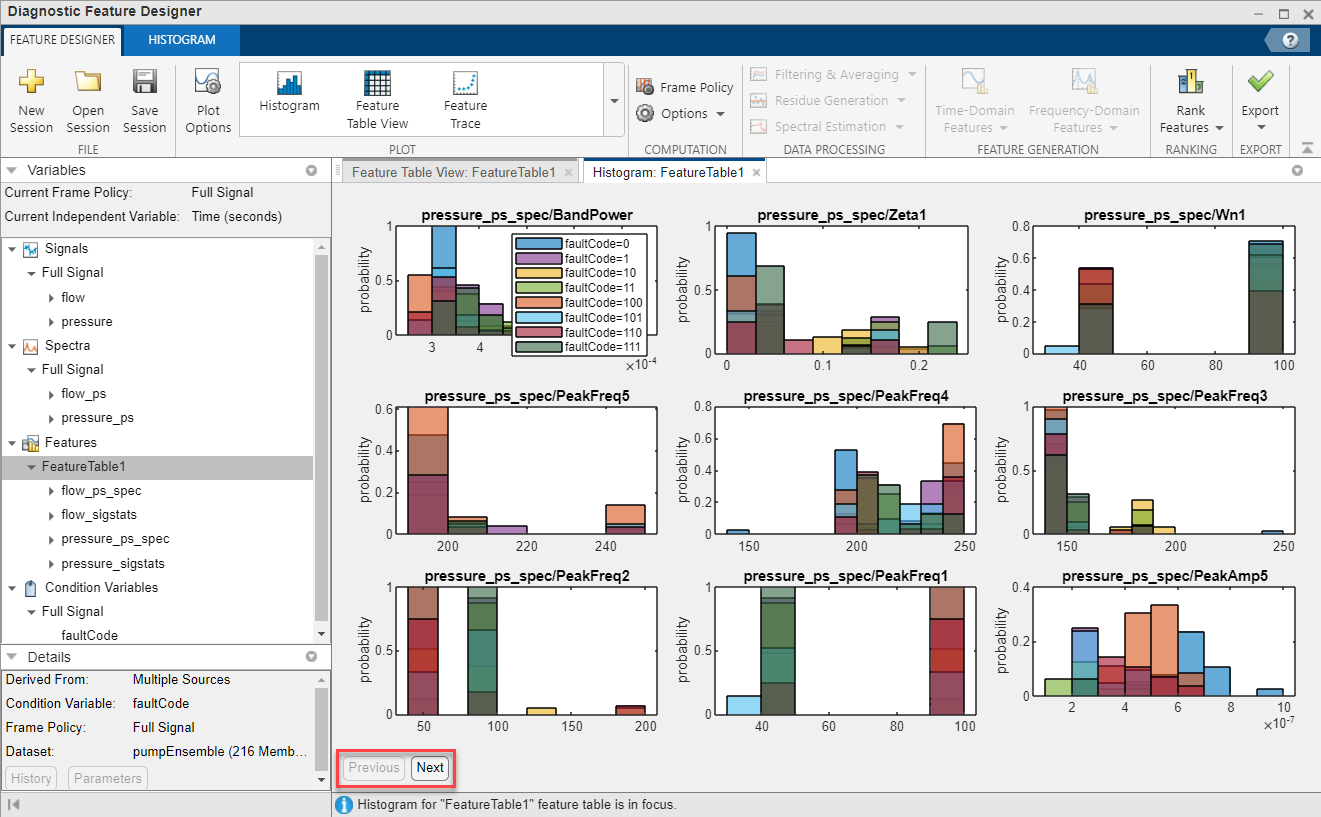

### 10. Clasificar características

Ahora que has extraído muchas características, ¿cómo sabes cuáles serán las mejores candidatas para entrenar un modelo de aprendizaje automático preciso? En el ***Diagnostic Feature Designer***, puedes clasificar las funciones para determinar la probabilidad de que tengan un buen poder predictivo. 

  Abre el cuadro de diálogo ***Rank Features*** desde la sección **FEATURE GENERATION** como se muestra a continuación y selecciona la tabla de funciones actual (`FeatureTable1` ) que has creado. 

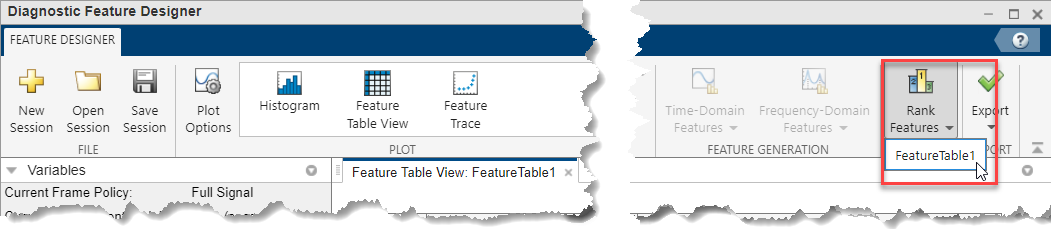

Esto recopila todos los datos de las características y los clasifica según una métrica como ANOVA. Luego, las características se enumeran en términos de importancia según el valor de la métrica. 

En este caso, puedes ver que el valor RMS para la señal de flujo y los valores RMS y medios para la señal de presión son las características que distinguen con mayor fuerza los diferentes tipos de fallas entre sí. 

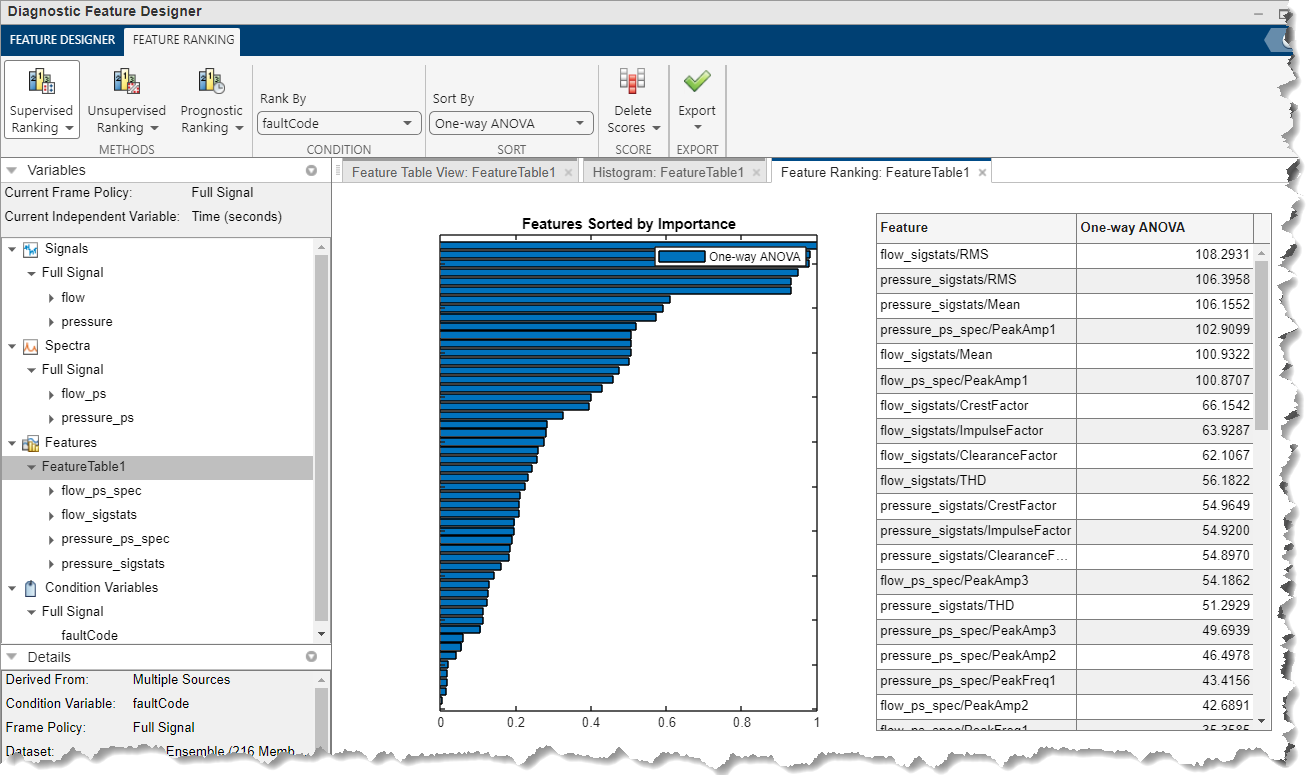

### >>Punto de control<<

Si deseas ponerte al día con este punto, puedes ejecutar: 

% PEGA EL CÓDIGO AQUÍ

### 11. Exportar funciones principales

Una vez que hayas clasificado las características (Features) en términos de de importancia, el siguiente paso es exportar las mejores para que puedas entrenar un modelo de clasificación basado en estas características. 

  En la pestaña **FEATURE RANKING**, haz clic en el menú desplegable ***Export***  y elige ***Export features to the MATLAB workspace****.*

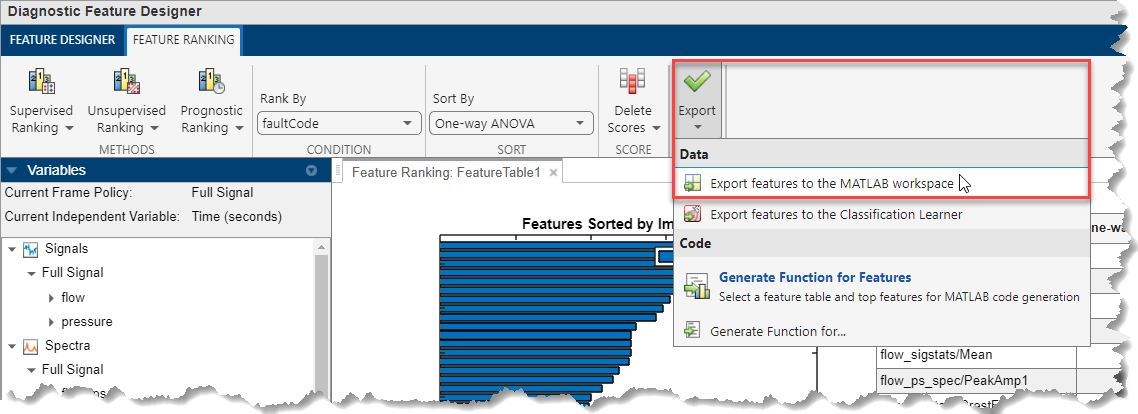

  Elige las `20` características principales y haz clic en **Export**: 

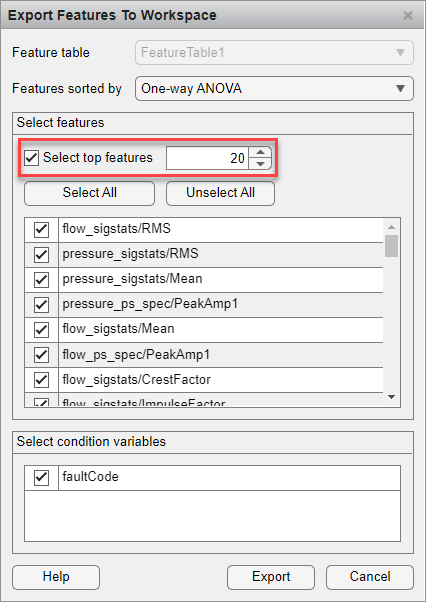

Luego, las características se envían a MATLAB espacio de trabajo en forma de tabla denominada `FeatureTable1`. 

  ***Nota *****:** También puedes exportar las funciones a la app **Classification Learner**, lo que le permite continuar con el flujo de trabajo interactivo para crear un modelo de aprendizaje automático y diseñar un clasificador para identificar diferentes fallas. Sin embargo, utilizaremos un enfoque programático en el resto de este ejercicio. Si hay tiempo al final del ejercicio, puedes intentarlo en la última sección (opcional). 

### 12. Generar una función para recalcular características

A menudo, querrás utilizar los mismos cálculos de extracción de características en datos nuevos. Para rehacer todo el trabajo que acabas de hacer de forma interactiva en la aplicación, puedes generar una función de MATLAB para volver a calcular estas características. **La app genera código que reproduce tanto el procesamiento de datos preliminares, como la extracción de características y la clasificación. **

  En la pestaña **FEATURE RANKING** selecciona la opción ***Export ****y* selecciona ***Generate Function for Features***: 

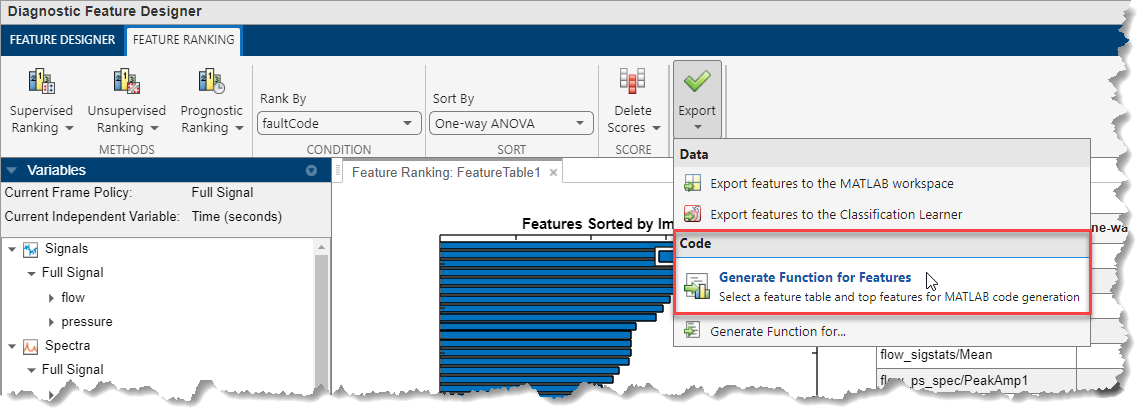

  Elige `20` como el número de funciones principales que se utilizarán en la función generada: 

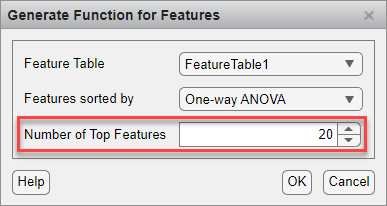

  Guarda la función generada en tu carpeta actual. 

## Entrenar un modelo de clasificación para identificar fallas

### 13. Volver a calcular características a partir de funciones generadas

Ya exportamos una función, `diagnosticFeatures`, que volverá a calcular todas las características que generamos anteriormente en la app **Diagnostic Feature Designer**. Esto nos permite utilizar la función en conjuntos de datos nuevos o más grandes, o en datos adquiridos de bombas nuevas. 

Calcula las características usando la función MATLAB generada llamada `diagosticFeatures `y` trainData` como entrada`.`

trainFeatures = diagnosticFeatures(trainData) 

A continuación, haz lo mismo para calcular características a partir de los datos de prueba (`testData`): 

testFeatures = diagnosticFeatures(testData)

### 14. Entrena modelos de clasificación

Ahora podemos entrenar una variedad de clasificadores en estas características para ver cuál predice con mayor precisión los códigos de falla de la bomba. Primero, entrena tres tipos de modelos en las características de entrenamiento: 

mdlTree = fitctree(trainFeatures, "faultCode"); 
mdlSVM = fitcecoc(trainFeatures, "faultCode"); 
mdlKNN = fitcknn(trainFeatures, "faultCode");

### 15. Compara el rendimiento del modelo

Para evitar sobreajustar nuestros datos de entrenamiento, debemos probar el rendimiento del modelo en datos en los que no fue entrenado: nuestras características de prueba `testFeatures`

Elige un modelo entrenado y utiliza la matriz de confusión para analizar los resultados. 

mdl = mdlKNN
predictTest = predict(mdl, testFeatures);
testGroundTruth = testFeatures.faultCode;
figure;
confusionchart(testGroundTruth, predictTest)
l = loss(mdl, testFeatures, 'faultCode')

## [Opcional] Entrena modelos de clasificación usando la aplicación* Classification Learner * 

En lugar de entrenar modelos mediante programación, también puede entrenar interactivamente una variedad de modelos de clasificación usando la app* Classification Learner*. 

 Para hacerlo, puedes exportar las funciones directamente desde la app *Diagnostic Feature Designer* a la app *Classification Learner*, seleccionando **Export** y luego **Export features to the Classification Learner**.

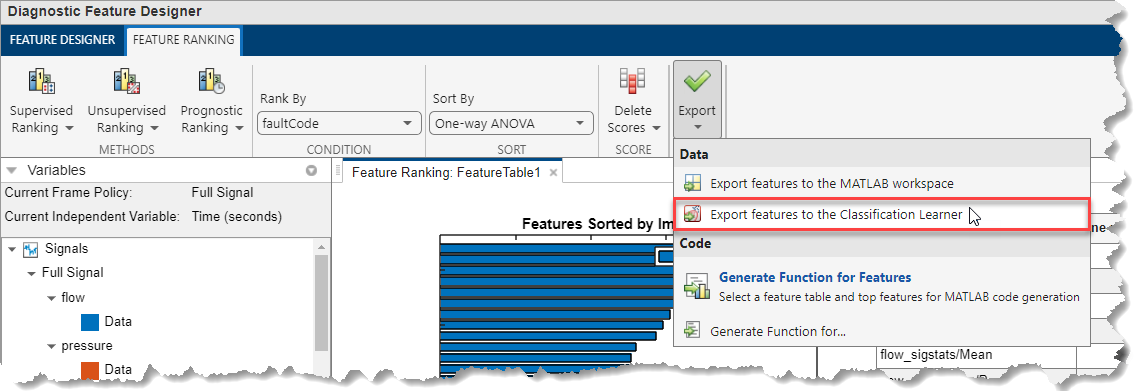

 Elige las `20` funciones principales que se exportarán a la aplicación Classification Learner y haz clic en ***Export***: 

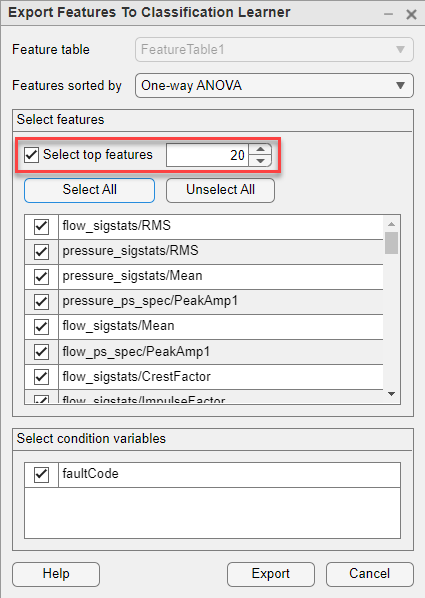

Una vez exportadas las funciones, puedes iniciar una nueva sesión a partir de las funciones obtenidas. Elige **Resubstitution Validation **como esquema de validación. Ten en cuenta que esto no proporciona protección contra el sobreajuste. Más adelante podrás probar los modelos entrenados con el conjunto de datos de prueba. 

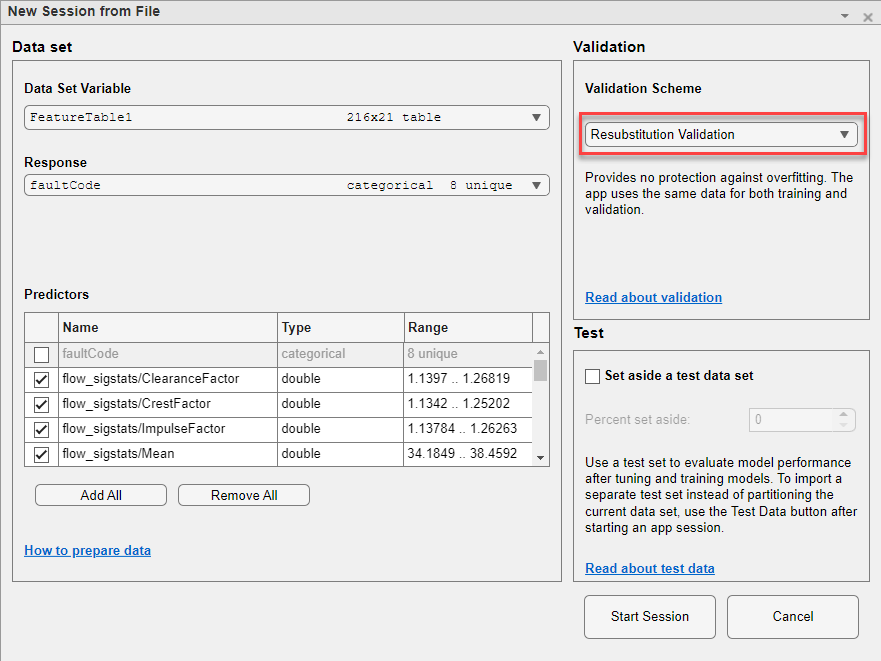

En este punto, puedes entrenar varios modelos de aprendizaje automático del catálogo **MODELS**: 

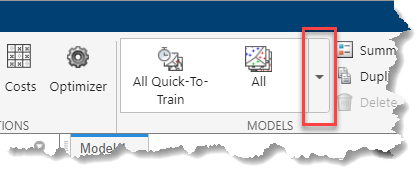

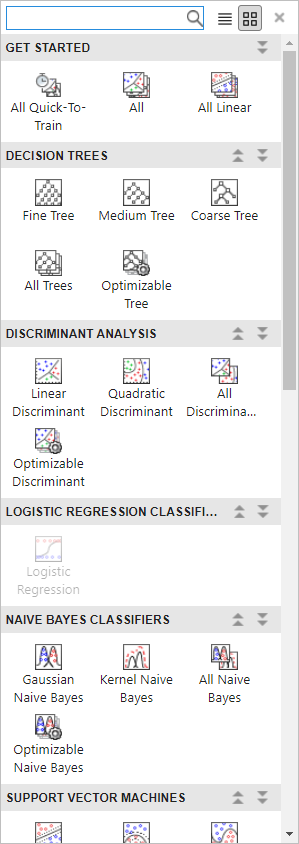

  Selecciona y entrena (**botón Train**) algunos modelos de aprendizaje automático: 

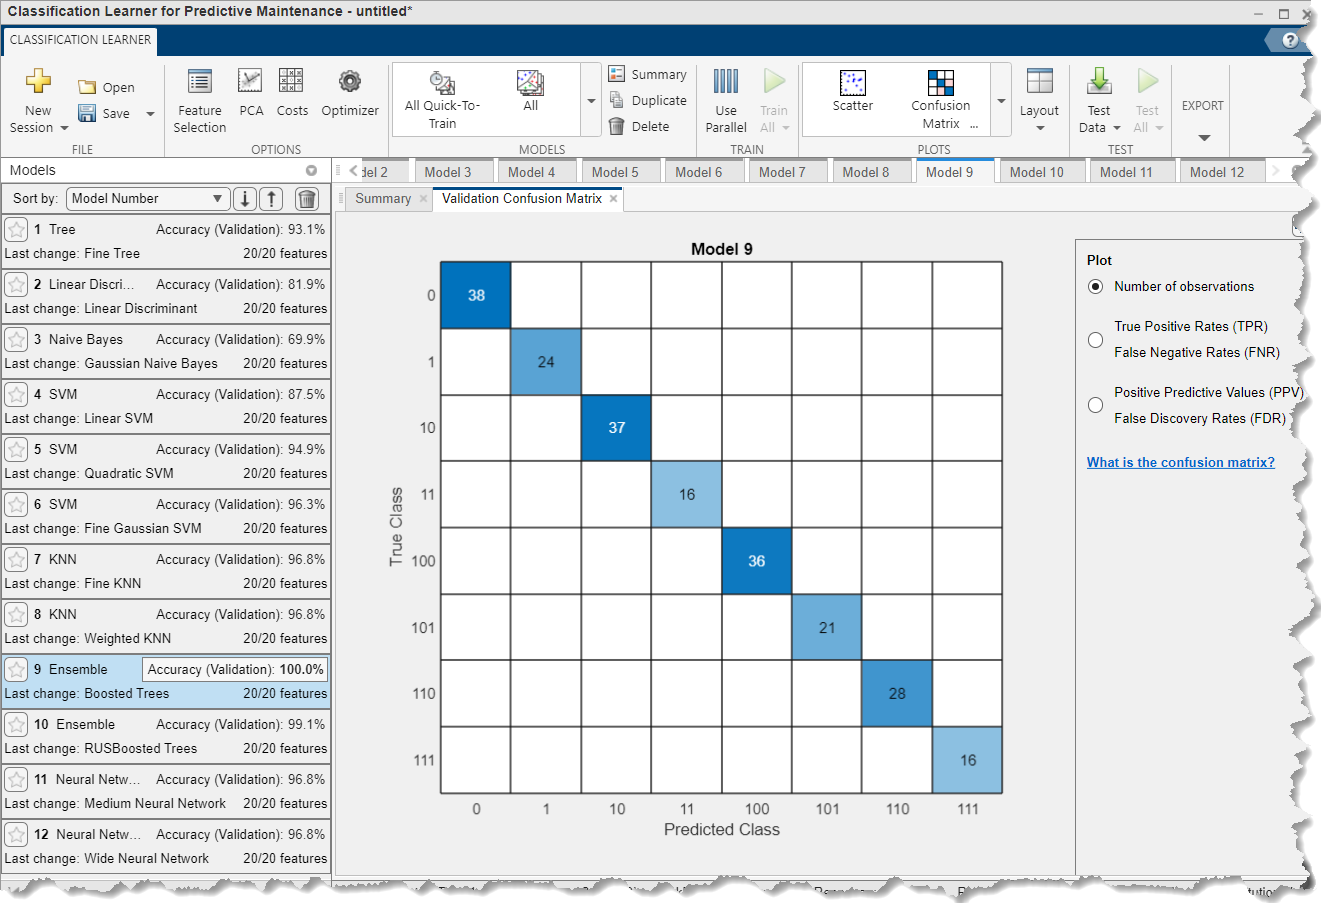

Ten en cuenta que la precisión del modelo es muy alta para los Boosted Trees y otros métodos. Es probable que esto se deba a un sobreajuste debido a la falta de un conjunto de datos de validación. Esto se hizo porque nuestro conjunto de datos era muy pequeño. 

En este punto, puedes utilizar un nuevo conjunto de datos para evaluar el rendimiento de los modelos frente a datos no vistos: 

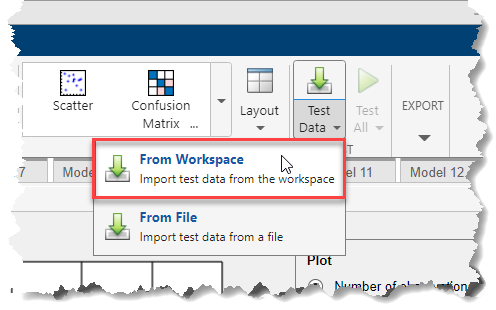

Proporciona las características de prueba calculadas (`testFeatures`): 

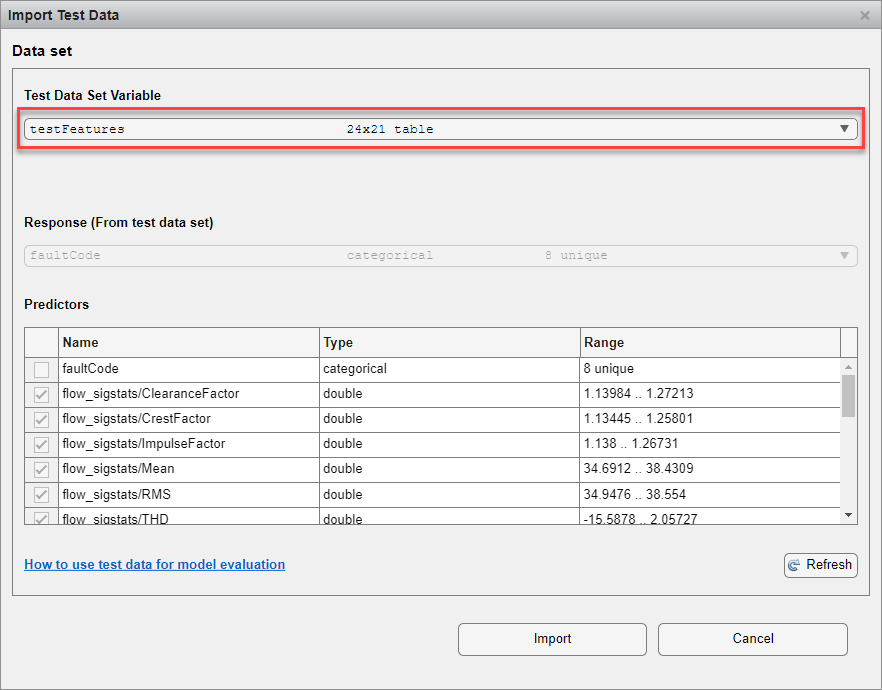

Prueba todos los modelos entrenados: 

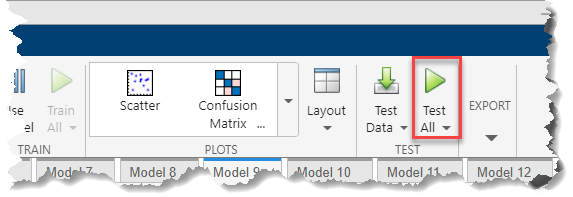

Verifica qué modelo proporciona la mayor precisión frente a los datos de prueba: 

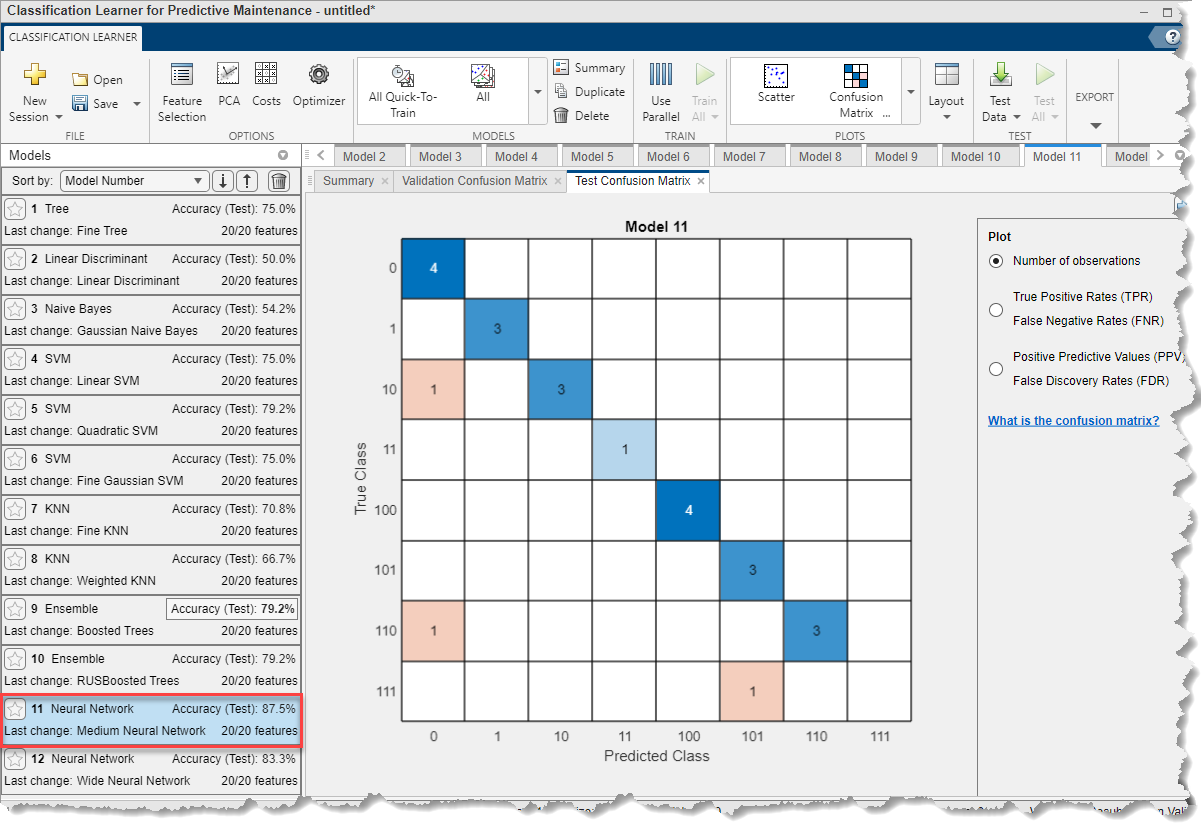

Para concluir, puedes exportar el modelo entrenado o generar una función para volver a entrenar el modelo: 

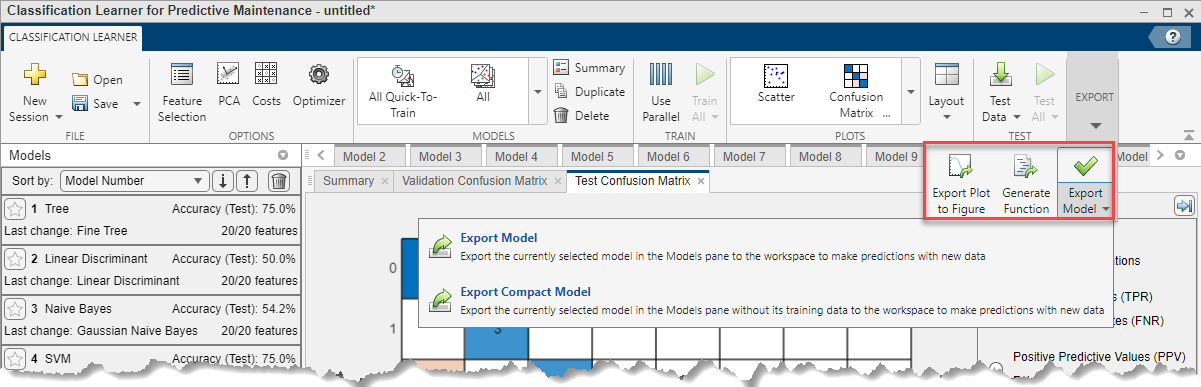

* Copyright 2024 The MathWorks, Inc. *